## Exercice : Fastcore & Fastcormics on a Toy Model 

*Author : Hugues Escoffier *

clear

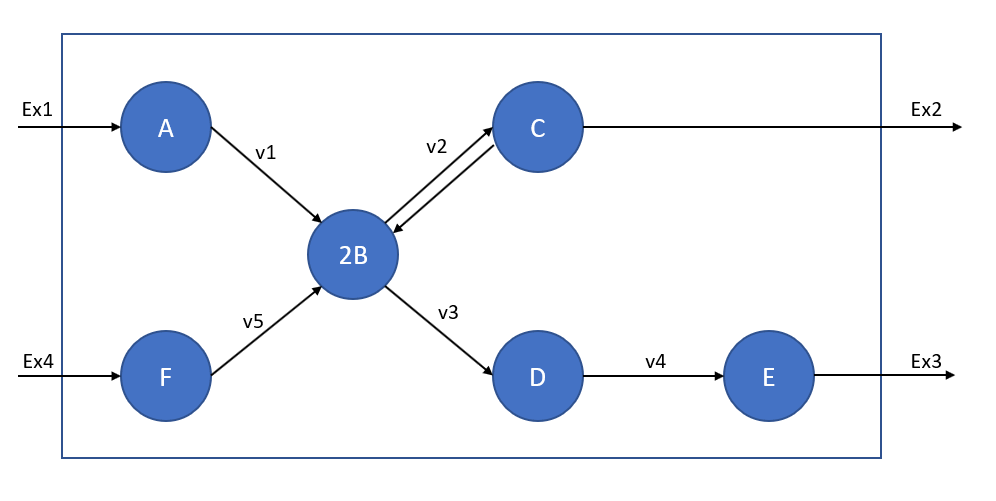

#### Question 1 : Create the model using the createModel function 

% Create model
ReactionFormulas = {'A -> 2 B','2 B <=> C', '2 B -> D','D -> E', 'F -> 2 B', ...
    'A <=>', 'C ->', 'E ->', 'F <=>'};
ReactionNames = {'v1','v2','v3', 'v4', 'v5', 'Ex1','Ex2','Ex3','Ex4'};
GeneNames={'Gene1','Gene2','Gene3', 'Gene4', 'Gene5','GeneEx1', 'GeneEx2', 'GeneEx3', 'GeneEx4'};
model = createModel(ReactionNames, ReactionNames, ReactionFormulas,'grRuleList',GeneNames);

Adding the following Metabolites to the model:
A[c]
B[c]
C[c]
D[c]
E[c]
F[c]
addMultipleReactions: Adding the following reactions to the model:
v1	A[c] 	->	2 B[c] 
v2	2 B[c] 	<=>	C[c] 
v3	2 B[c] 	->	D[c] 
v4	D[c] 	->	E[c] 
v5	F[c] 	->	2 B[c] 
Ex1	A[c] 	<=>	
Ex2	C[c] 	->	
Ex3	E[c] 	->	
Ex4	F[c] 	<=>	


#### Question 2 : Is the model consistent ? 

% Enter your code here
fastcc_4_rfastcormics(model, 1e-4, 0)


The input model is consistent.
Elapsed time is 0.004285 seconds.


ans =      1
     2
     3
     4
     5
     6
     7
     8
     9


#### Question 3: 

- 1. Find and print the exchange reactions that are importing these metabolites from the cell into the model.

% Enter your code here
[EX] = findExcRxns(model); % Find all exchange reactions
printRxnFormula(model, model.rxns(find(EX))); % Shows all exchange reactions)

Ex1	A[c] 	<=>	
Ex2	C[c] 	->	
Ex3	E[c] 	->	
Ex4	F[c] 	<=>	


 In this exercice, we want the model to be able to exchange only with the metabolites present in the medium. 

medium = {'A[c]'}

medium = 1×1 cell array
    {'A[c]'}


- 2. Find the reactions that are open in the model regarding the medium  

% Enter your code here
[Ex_open] = findRxnsFromMets(model, medium)

Ex_open = 2×1 cell array
    {'v1' }
    {'Ex1'}


- 3. Based on the results of the previous questions, find exchanges reactions that should be unable to carry a flux and save them in a variable.

% Enter your code here
Ex_to_close=setdiff(model.rxns(EX),Ex_open)

Ex_to_close = 3×1 cell array
    {'Ex2'}
    {'Ex3'}
    {'Ex4'}


- 4. Block reactions from carrying a flux by changing the corresponding bound to 0. Then run FASTCC again on the medium constrained model. 

% Enter your code here
model.lb(ismember(model.rxns,Ex_to_close)) = 0

model = struct with fields:
          rxns: {9×1 cell}
             S: [6×9 double]
            lb: [9×1 double]
            ub: [9×1 double]
             c: [9×1 double]
          mets: {6×1 cell}
             b: [6×1 double]
         rules: {9×1 cell}
         genes: {9×1 cell}
     osenseStr: 'max'
        csense: [6×1 char]
    rxnGeneMat: [9×9 double]
      metNames: {6×1 cell}
    subSystems: {9×1 cell}
       grRules: {9×1 cell}
      rxnNames: {9×1 cell}


- 5. Run FASTCC to obtain again a medium constrained model:

% Enter your code here
A = fastcc_4_rfastcormics(model, 1e-4, 0);

Elapsed time is 0.001193 seconds.


medium_constrained_consistent_model=removeRxns(model,model.rxns(setdiff(1:numel(model.rxns),A)))

medium_constrained_consistent_model = struct with fields:
          rxns: {7×1 cell}
             S: [5×7 double]
            lb: [7×1 double]
            ub: [7×1 double]
             c: [7×1 double]
          mets: {5×1 cell}
             b: [5×1 double]
         rules: {7×1 cell}
         genes: {9×1 cell}
     osenseStr: 'max'
        csense: [5×1 char]
    rxnGeneMat: [7×9 double]
      metNames: {5×1 cell}
    subSystems: {7×1 cell}
       grRules: {7×1 cell}
      rxnNames: {7×1 cell}


#### **Question 4: **

in this part we want to mazimize the Ex3 reaction. 

- 1. Find the index for the Ex3 reaction 

% Enter your code here
index_objective_rxn = find(ismember(medium_constrained_consistent_model.rxns, 'Ex3')); 

- 2. Change objective 

% Enter your code here
medium_constrained_consistent_model = changeObjective(medium_constrained_consistent_model,medium_constrained_consistent_model.rxns(index_objective_rxn));

- 3. Optimize the model to maximize the objective of the model

% Enter your code here
solution = optimizeCbModel(medium_constrained_consistent_model,'max') 

solution = struct with fields:
    origStatText: 'Optimal solution found'
               f: 1000
              f0: NaN
              f1: 1000
              f2: NaN
               v: [7×1 double]
               y: [5×1 double]
               w: [7×1 double]
               s: [5×1 double]
          solver: 'ibm_cplex'
       algorithm: 'Automatic'
            stat: 1
        origStat: 1
            time: 0.0160
           basis: [1×1 struct]
          vars_v: []
               x: [7×1 double]


#### Question 5: 

- **Core reactions : v1, v3 **

Add core reactions : 

- 1. Using Fastcore

list_core_reactions = {'v1', 'v3'};

In order to run fastcore, you need a list of core reaction indexes. 

                    a. Create a list containing the cores reactions indexes (v1 and v3)

% Enter your code here
list_index_core_reactions = [];
for i = 1:length(list_core_reactions)
    index_core_rxn = find(ismember(medium_constrained_consistent_model.rxns, list_core_reactions(i)));
    list_index_core_reactions(end +1) = index_core_rxn;
end

                    b. Run the fastcore() function 

**fastcore() **

Input :

- **model** : S - *m x 1* Stoichiometric matrix * lb - *n x 1* Lower bounds * ub - *n x 1* Upper bounds * rxns - *n x 1* cell array of reaction abbreviations

- **core** : Indices of reactions in cobra model that are part of the core set of reactions

- *epsilon : Smallest flux value that is considered nonzero (default 1e-4)*

- *printLevel : 0 = silent, 1 = summary, 2 = debug (default - 0)*

Output: 

- **tissueModel** : extracted model

- *coreRxnBool : n x 1 boolean vector indicating core reactions*

More informations : [https://opencobra.github.io/cobratoolbox/stable/modules/dataIntegration/transcriptomics/FASTCORE/index.html](https://opencobra.github.io/cobratoolbox/stable/modules/dataIntegration/transcriptomics/FASTCORE/index.html) 

% Enter your code here
fastcore_model = fastcore(medium_constrained_consistent_model, list_index_core_reactions, 1e-4)

LP10: Adaptive scaling factor did not work, switching to fixed scaling factor of 1e4


fastcore_model = struct with fields:
          rxns: {5×1 cell}
             S: [4×5 double]
            lb: [5×1 double]
            ub: [5×1 double]
             c: [5×1 double]
          mets: {4×1 cell}
             b: [4×1 double]
         rules: {5×1 cell}
         genes: {5×1 cell}
     osenseStr: 'max'
        csense: [4×1 char]
    rxnGeneMat: [5×5 double]
      metNames: {4×1 cell}
    subSystems: {5×1 cell}
       grRules: {5×1 cell}
      rxnNames: {5×1 cell}


- 2. Using Fastcormics

For fastcormircs, unlike fastcore requires a matrix in which each gene is associated with a number: 

- 0 if unknown

- 1 if expressed (core reaction)

- -1 if not expressed (inactive)

% Optional settings 
optional_settings = struct;
optional_settings.unpenalized = {};
optional_settings.func = {'Ex3'};
optional_settings.not_medium_constrained = {};

rownames = medium_constrained_consistent_model.genes; % Change according to the name of your model
dico = table(medium_constrained_consistent_model.genes, medium_constrained_consistent_model.genes); % Change according to the name of your model
biomass_rxn = 'Ex3'; 
already_mapped_tag = 0;
consensus_proportion = 1;
epsilon = 1e-4;

                    a. Create a discretize matrix based on the core reactions 

% Enter your code here
discritized = [1;0;1;0;0;0;0;0;0];

                    b. Run fastcormics_RNAseq function 

**fastcormics_RNAseq()**

Input : 

- **model **: Model use to extract the context-specific model from

- **data** : Matrix with *n* rows (1 per genes) and *m* columns (1 per sample) with 1 for expressed genes, 0 for unknown expression and -1 for unexpressed genes. 

- *rownames : The gene names for each row in the data*

- *dico :  Dictionary to map the gene names to the gene names in the model (e.g. Entrez to EnsemblID)*

- *biomass_rxn : Rxn that is (generally) to be maximized*

- *already_mapped_tag :  0 if the data has not been mapped to the GPR rules of the model, 1 otherwise*

- *consensus_proportion :  In the case where several samples are used to reconstruct a model*

- *epsilon :  Flux threshold value (1e-4)*

- *optional_settings : Structure containing 4 elements.*

Output: 

- **model** : 

- **A_final** : 

% Enter your code here
[model, A_final] = fastcormics_RNAseq(medium_constrained_consistent_model, discritized, rownames, dico, biomass_rxn, already_mapped_tag, consensus_proportion, epsilon, optional_settings)

creating model.rev
unnesting subsystems


Temporarily removing transcripts...
9 of 9 genes matched



The input model is consistent.
Elapsed time is 0.001313 seconds.


model = struct with fields:
          rxns: {5×1 cell}
             S: [4×5 double]
            lb: [5×1 double]
            ub: [5×1 double]
             c: [5×1 double]
          mets: {4×1 cell}
             b: [4×1 double]
         rules: {5×1 cell}
         genes: {9×1 cell}
     osenseStr: 'max'
        csense: [4×1 char]
    rxnGeneMat: [5×9 double]
      metNames: {4×1 cell}
    subSystems: {5×1 cell}
       grRules: {5×1 cell}
      rxnNames: {5×1 cell}
           rev: [5×1 double]


A_final =      1
     3
     4
     5
     7


                    c. Create a model from the A_final array. 

First, create a logical matrix with the samples as columns and the reactions as rows in which 1 depicts if a reaction should take place in the context-specific model.

% Enter your code here
models_keep = zeros(numel(medium_constrained_consistent_model.rxns), 1);
models_keep(A_final,1) = 1; 

Then, remove the unwanted reactions using the *removeRxns* function from the model.

% Enter your code here
medium_core_constrained_consistent_model = removeRxns(medium_constrained_consistent_model,medium_constrained_consistent_model.rxns(setdiff(1:numel(medium_constrained_consistent_model.rxns),find(models_keep(:,1)))))